# Setting up

clc
clear;

addpath('.\sensordata\')
addpath('.\Helper functions\')

run startup.m

Loading: D:\Chalmers\SSY345_Sensor Fusion\Project\Sensorfusion smartphone\sensordata.jar


## Establishing connection

********************
* SensorDataReader started on 192.168.0.177:3400
********************
Connection accepted from 192.168.0.164:47905


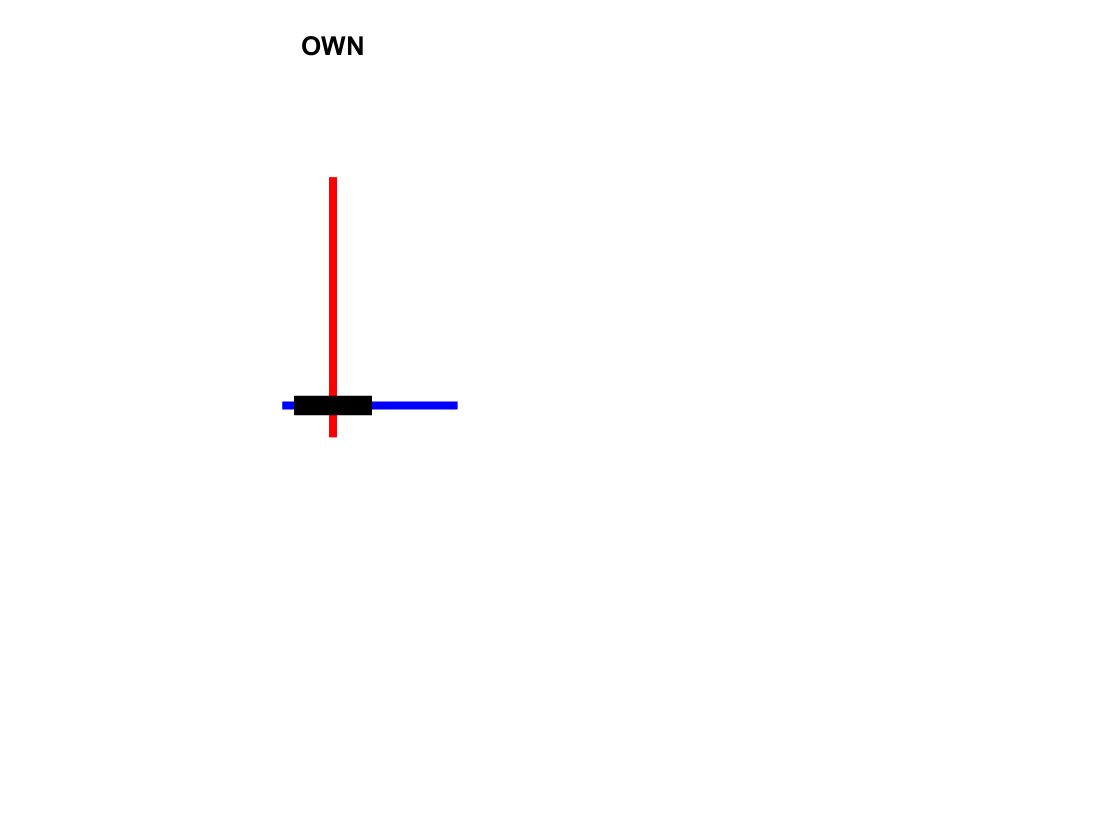

[xhat, meas] = filterTemplate();

## Plotting

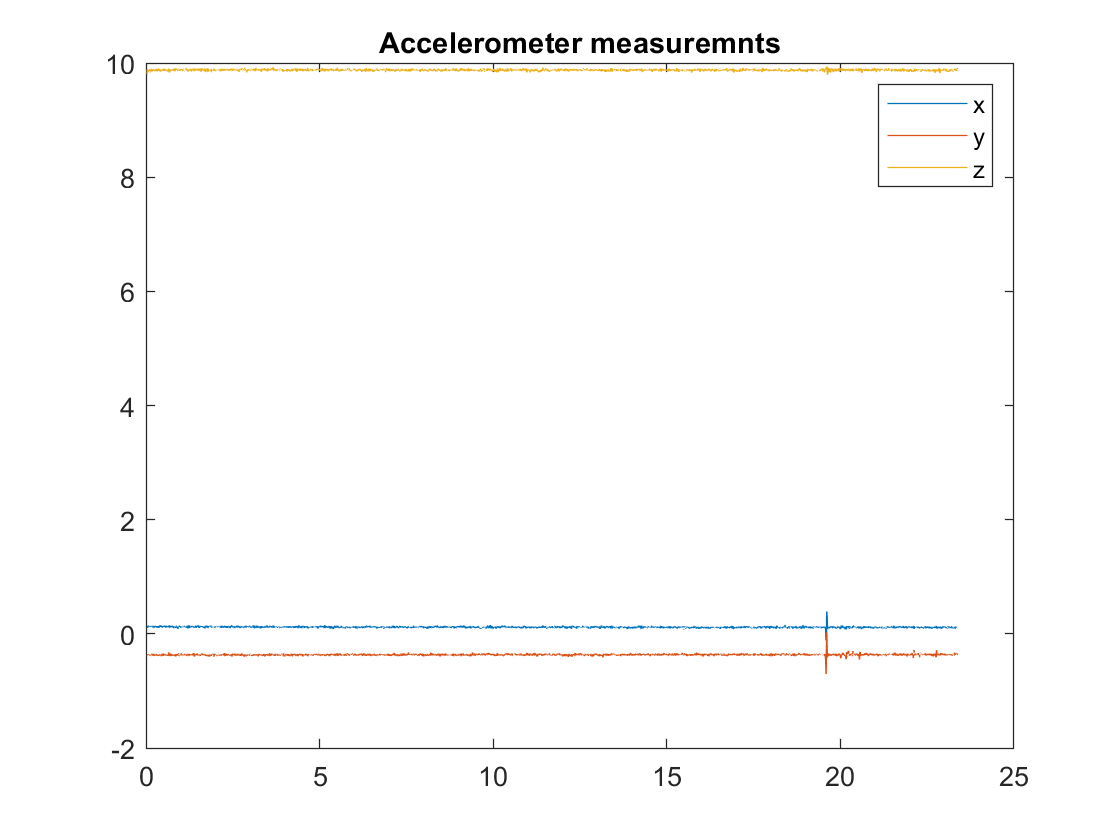

clf;
figure()
plot(meas.t, meas.acc)
title('Accelerometer measuremnts')
legend('x', 'y', 'z')

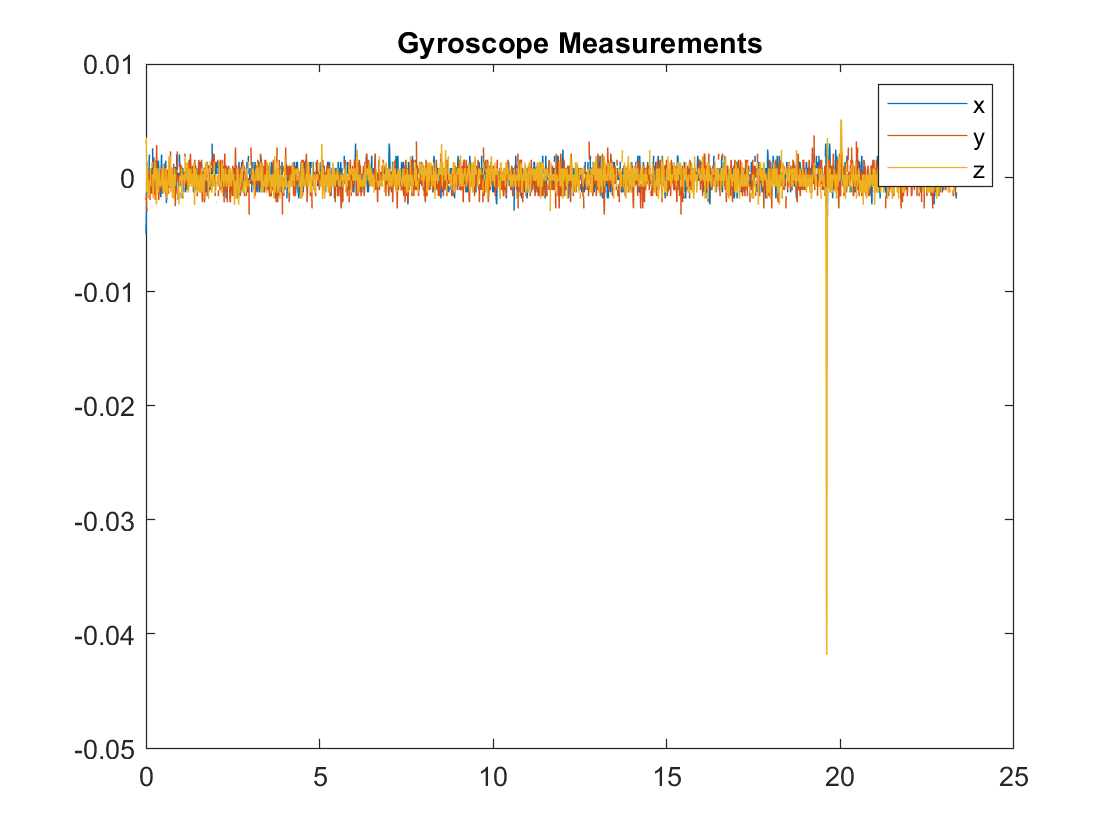

% print('./Images/Acc_meas_flat','-dpng')

figure()
plot(meas.t, meas.gyr)
title('Gyroscope Measurements')
legend('x', 'y', 'z')

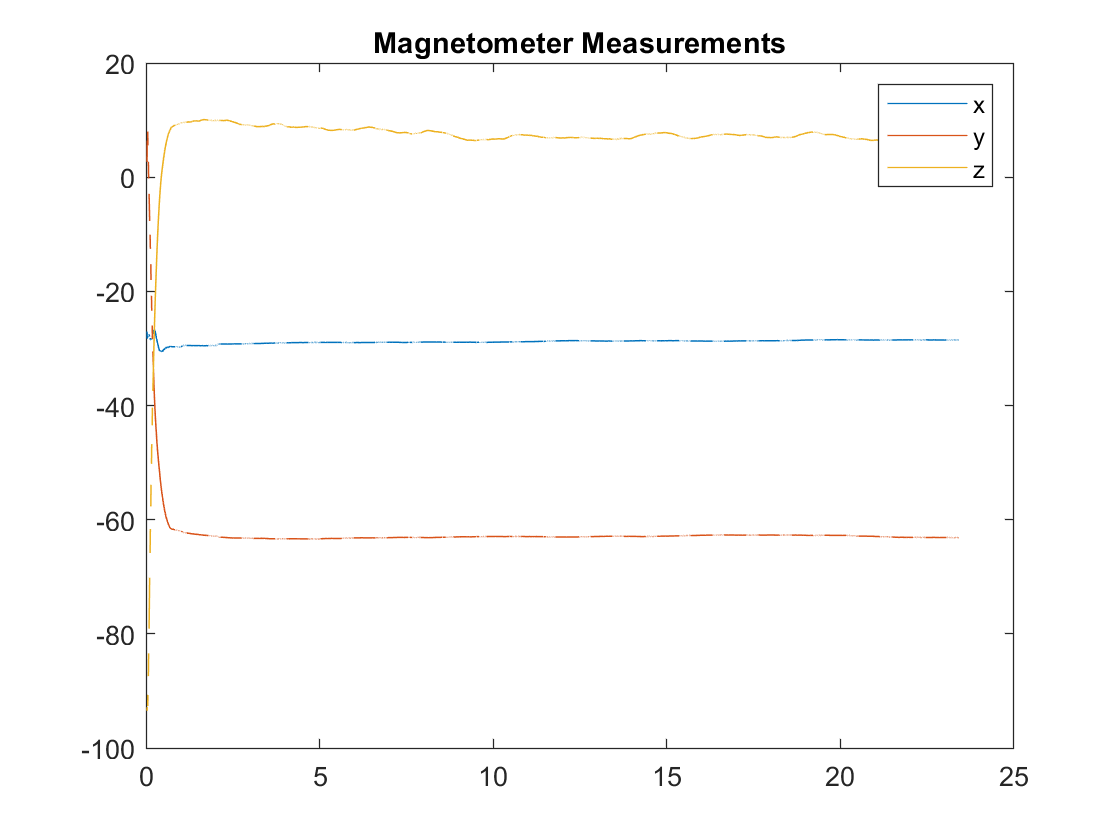

% print('./Images/Gyro_meas_flat','-dpng')

figure()
plot(meas.t, meas.mag)
title('Magnetometer Measurements')
legend('x', 'y', 'z')
% print('./Images/Mag_meas_flat','-dpng')

## Computing mean and covariance

% Accelerometer measurements
acc_mean = mean(meas.acc(:, ~any(isnan(meas.acc), 1)), 2)

acc_mean =     0.1170
   -0.3659
    9.8766


cov_acc = cov(meas.acc(:, ~any(isnan(meas.acc), 1)).')

cov_acc = 	1.0e+-3 *

    0.2168    0.0925    0.0107
    0.0925    0.3040    0.0031
    0.0107    0.0031    0.2236


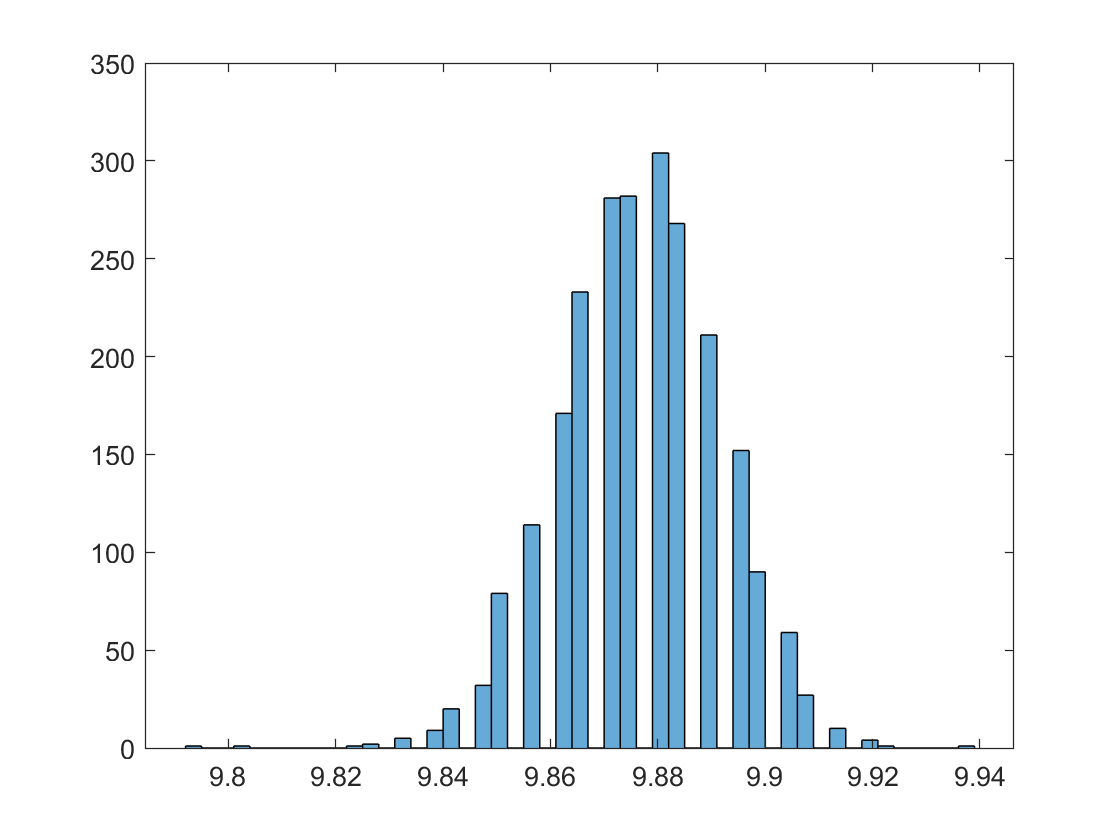

histogram(meas.acc(3, ~any(isnan(meas.acc), 1)))

% histogram(meas.acc(2, ~any(isnan(meas.acc), 1)))
% histogram(meas.acc(1, ~any(isnan(meas.acc), 1)))

% Gyroscope measurements
acc_gyr = mean(meas.gyr(:, ~any(isnan(meas.gyr), 1)), 2)

acc_gyr = 	1.0e+-3 *

    0.0608
   -0.1367
   -0.1189


cov_gyr = cov(meas.gyr(:, ~any(isnan(meas.gyr), 1)).')

cov_gyr = 	1.0e+-5 *

    0.0692    0.0013   -0.0060
    0.0013    0.1010    0.0111
   -0.0060    0.0111    0.2059


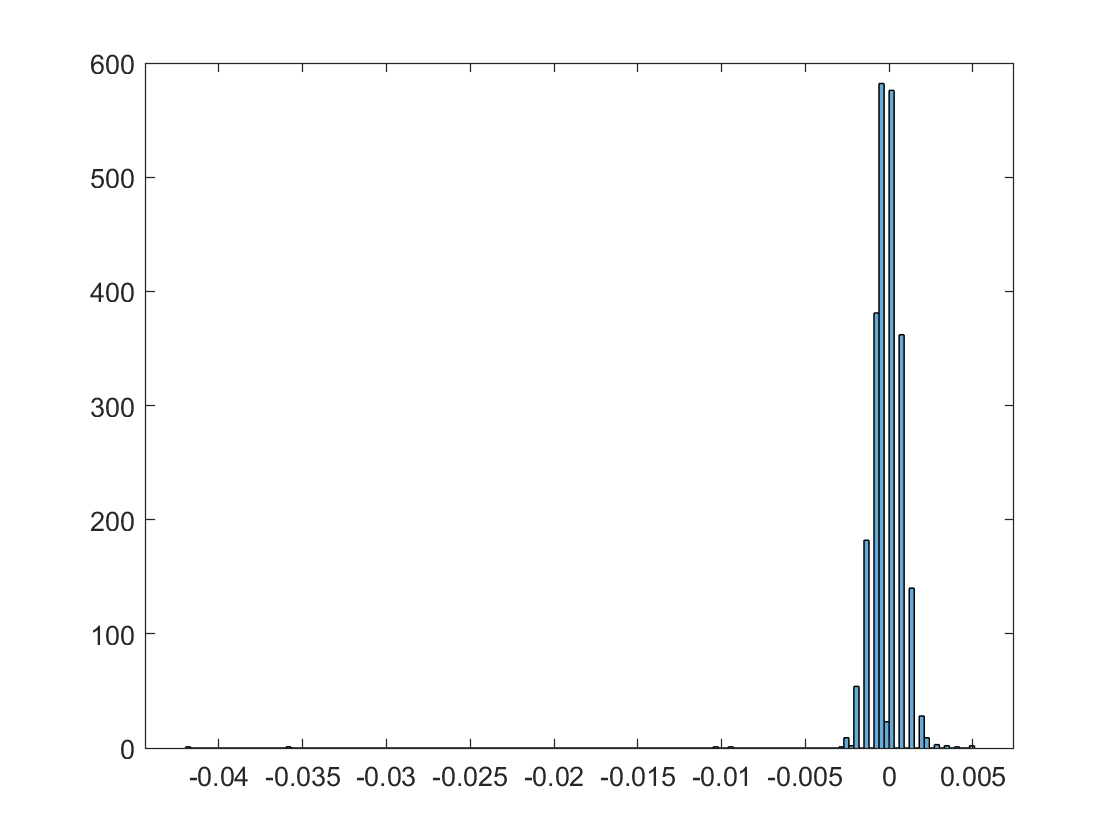

histogram(meas.gyr(3, ~any(isnan(meas.gyr), 1)))


% Magnetometer measurements
acc_mag = mean(meas.mag(:, ~any(isnan(meas.mag), 1)), 2)

acc_mag =   -28.8218
  -62.3334
    6.7544


cov_mag = cov(meas.mag(:, ~any(isnan(meas.mag), 1)).')

cov_mag =     0.1154    0.4005   -0.8732
    0.4005   26.2942  -36.8385
   -0.8732  -36.8385   53.0396


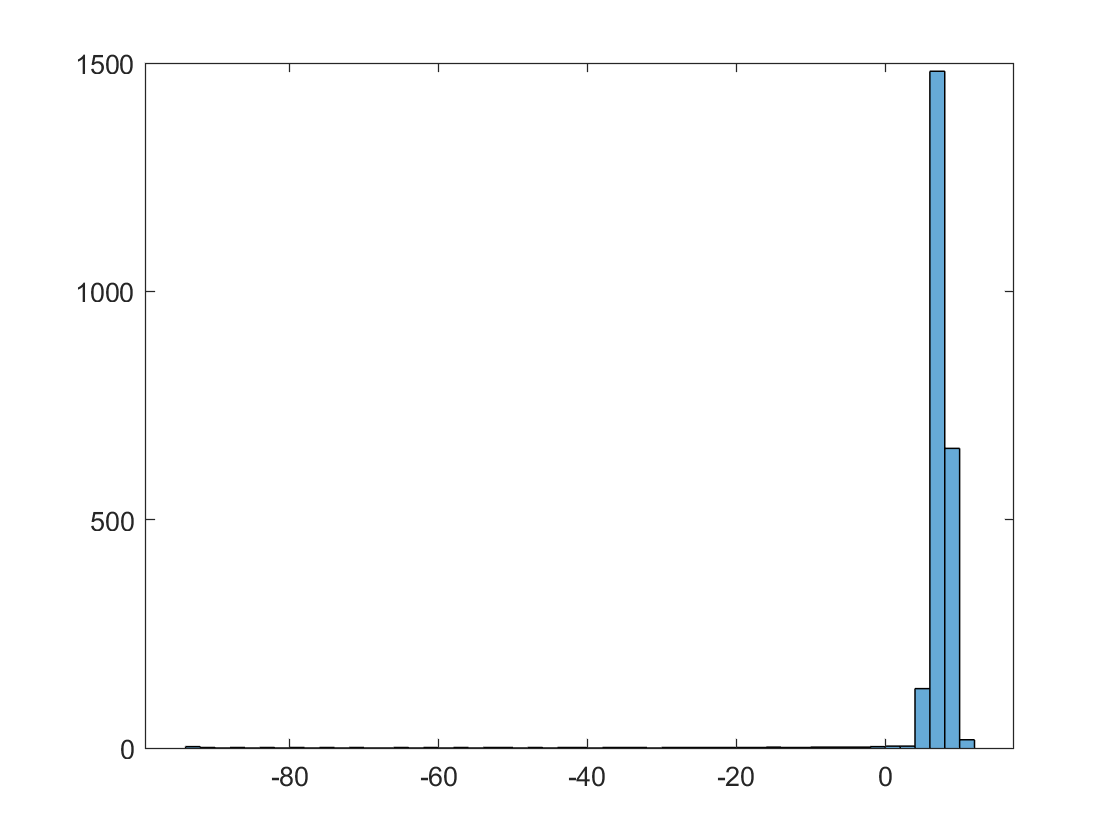

histogram(meas.mag(3, ~any(isnan(meas.mag), 1)))

## Task 4

x = ones(4,1);
P = rand(4);

omega = rand(3,1);
T = 0.1;
Rw = rand(3);

[x, P] = tu_qw(x, P, omega, T, Rw);
% [x, P] = tu_qw(x, P, gyr, t-xhat.t, P);

## Task 5

********************
* SensorDataReader started on 192.168.0.177:3400
********************
Connection accepted from 192.168.0.164:48027


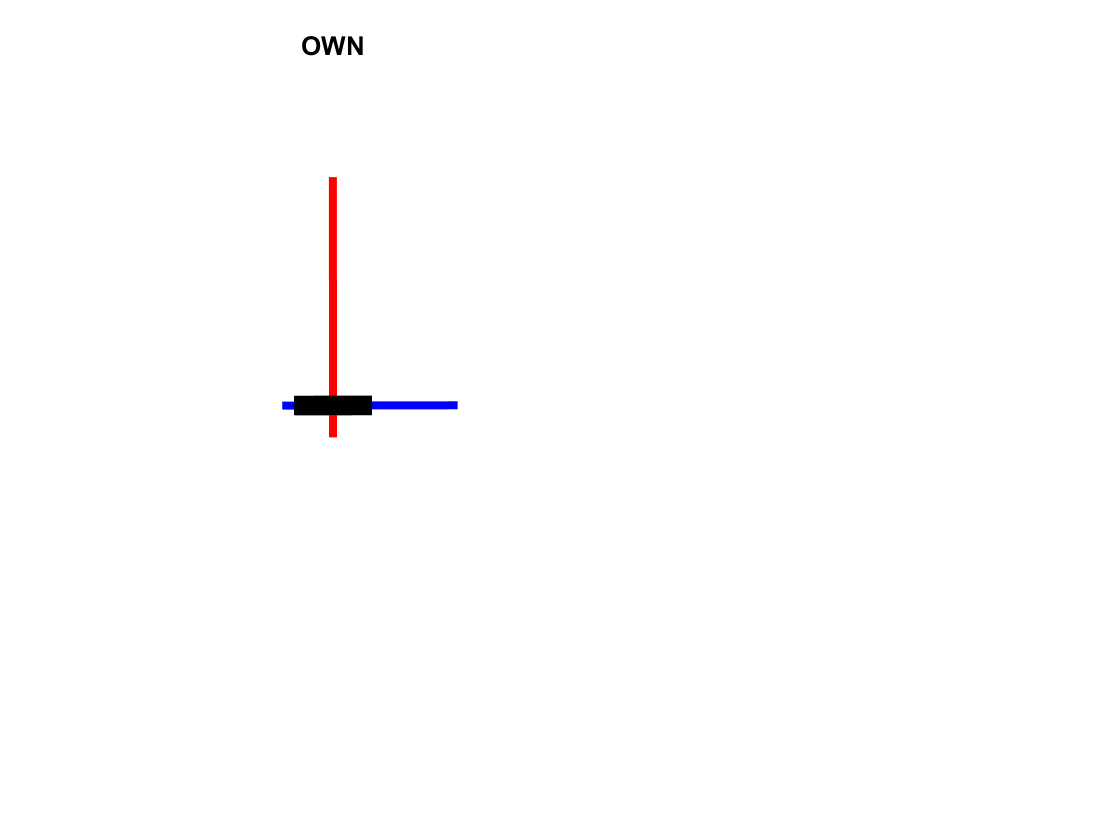

[xhat2, meas2] = Myfilter();